# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 05:25

## Create the Array of Layers

Mylayers = [
    imageInputLayer([32 32 3],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv_1")
    reluLayer("Name","relu_1")
    convolution2dLayer([3 3],64,"Name","conv_2")
    reluLayer("Name","relu_2")
    maxPooling2dLayer([3 3],"Name","maxpool_1")
    fullyConnectedLayer(1024,"Name","fc1")
    fullyConnectedLayer(256,"Name","fc2")
    dropoutLayer(0.4,"Name","dropout")
    fullyConnectedLayer(64,"Name","fc3")
    fullyConnectedLayer(16,"Name","fc4")
    fullyConnectedLayer(4,"Name","fc5")
    fullyConnectedLayer(1,"Name","fc")
    regressionLayer("Name","regressionoutput")];

## Plot the Layers

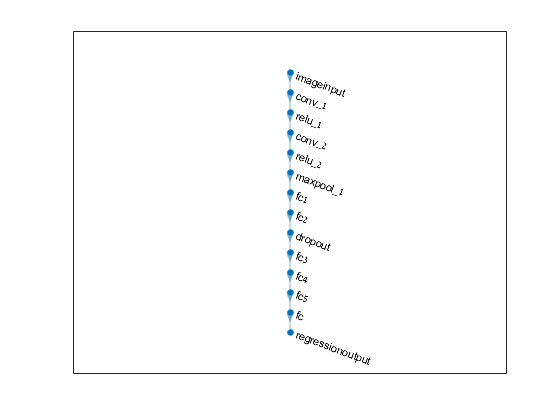

plot(layerGraph(Mylayers));